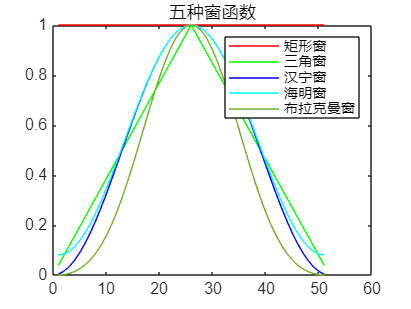

clc;clear;                    % 清除命令窗口和工作区变量

% 生成不同类型的窗函数，长度均为51点
%选择51的原因：①对称性②从分辨率和计算量两个方向考虑
a=boxcar(51);                 % 矩形窗
b=triang(51);                 % 三角窗
c=hanning(51);               % 汉宁窗
d=hamming(51);               % 海明窗
e=blackman(51);              % 布拉克曼窗
n=1:1:51;                    % 创建横坐标数组

% 绘制五种窗函数的对比图
figure(1);
plot(n,a,'r',n,b,'g',n,c,'b',n,d,'c',n,e);
legend('矩形窗','三角窗','汉宁窗','海明窗','布拉克曼窗');
title('五种窗函数');

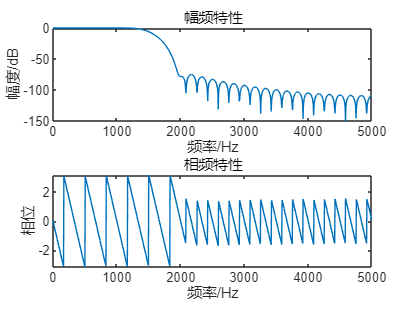


% 使用布拉克曼窗设计FIR滤波器
T=0.0001;                    % 采样周期
fs=1/T;                      % 采样频率
wp=1000*2*pi/fs;            % 通带截止频率
ws=2000*2*pi/fs;            % 阻带截止频率
wide=ws-wp;                  % 计算过渡带宽度
N=ceil(12*pi/wide);         % 计算所需窗长度（向上取整）
wc=(wp+ws)/2;               % 计算截止频率
% 这里直接/2是使wc位于过渡带中间，均衡通带阻带性能，使过渡带性能提升
% 使用fir1函数设计FIR滤波器
h=fir1(N,wc/pi,blackman(N+1));  % 设计滤波器，使用布拉克曼窗

% 计算滤波器的频率响应
[H,w]=freqz(h,1,1000);      % 计算频率响应
dB=20*log10(abs(H));        % 将幅度转换为分贝形式

% 绘制滤波器的幅频和相频特性
figure(2);
subplot(2,1,1);             % 绘制幅频特性
plot(w/2/pi*fs,dB);
xlabel('频率/Hz');ylabel('幅度/dB');
title('幅频特性');

subplot(2,1,2);             % 绘制相频特性
plot(w/2/pi*fs,angle(H));
xlabel('频率/Hz');ylabel('相位');
title('相频特性');